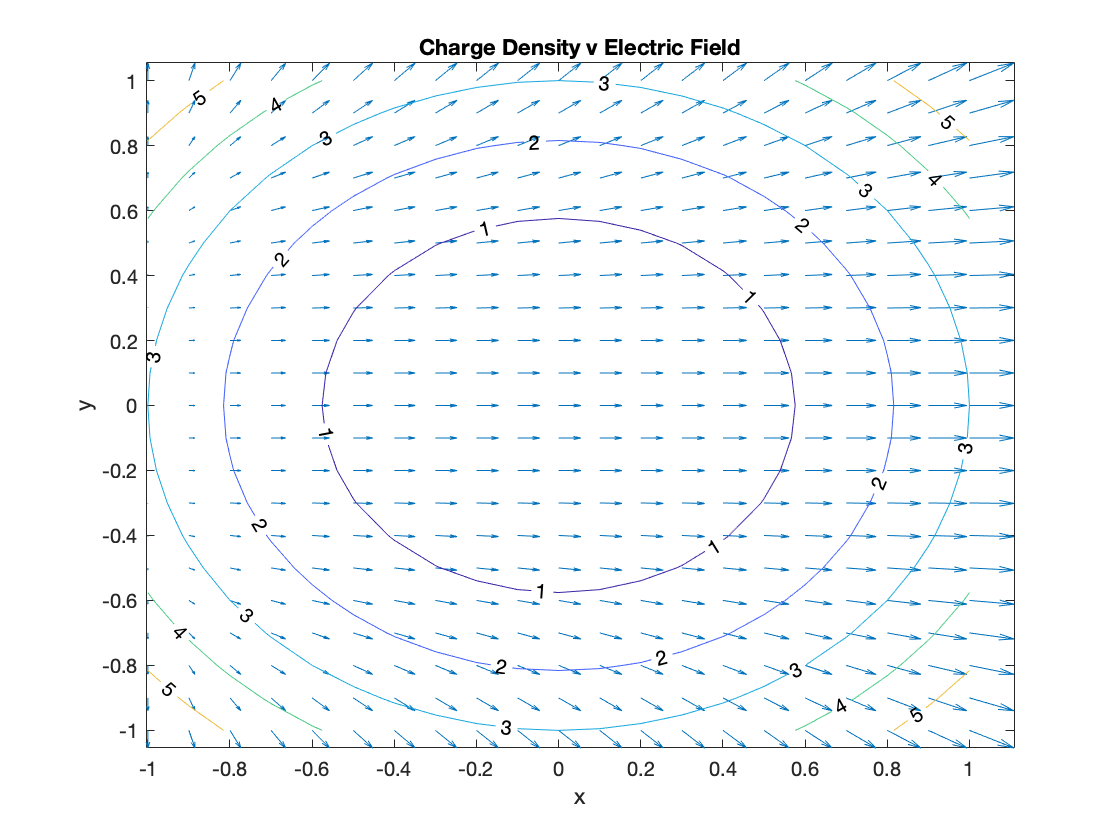

syms x y epesilon0 t
E = [(x^3+1) y^3];
chargedensity= epesilon0*divergence(E,[x y]);
chargedensity = subs(chargedensity,epesilon0,1);
v = [-1:0.1:1];
[xcontour,ycontour] = meshgrid(v);
    Ex = subs(E(1),x,xcontour);
    Ey = subs(E(2),y,ycontour);
densityPlot = subs(chargedensity,{x,y},{xcontour,ycontour});
quiver(xcontour,ycontour,Ex,Ey)
hold on
contour(xcontour,ycontour,densityPlot,'ShowText','on')
title('Charge Density v Electric Field')
xlabel('x')
ylabel('y')

v0 = [5 0 0];  %initial velocity 
E = [(x^3+1) y^3 0];
q = -1;
B = [2*x -2*y 0];
k = 8.99e9;
v = q*[E + cross(v0,B)]/(9.10938356e-31)*t;






